## Exame 114588 113534

#### Henrique Teixeira

#### Maria Linhares

## Parte II

[x, t, num, den] = exame2(1223, 2);
a=diff(t);


### 1.

variavel a = periodo de amostragem

fa = 1./a(1,1);

fprintf('Frequência de amostragem = %d', fa);

Frequência de amostragem = 400

### 2.

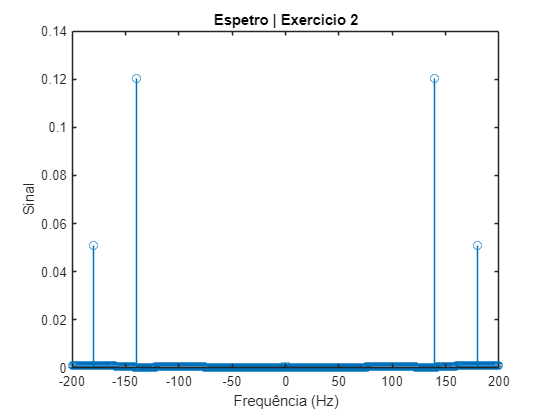

y = filter(num,den,x);
[~,~] = espetro(y,1/fa);
title('Espetro | Exercicio 2');

### 3.

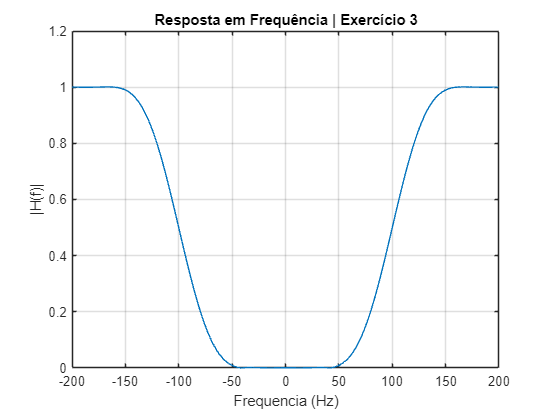

[~,~] = respfreq(num,den,fa);
title('Resposta em Frequência | Exercício 3');


% justificação
% o espectro do sinal é influenciado pela resposta em frequência do filtro. 
% As características do filtro determinam quais as frequências atenuadas no sinal de saída
% Podemos ver isto nos picos e vales do gráfico

### 4.



atraso = 0.140; % 140 milisegundos
D = round(atraso*fa);

fprintf('Valor de D = %d', D);

Valor de D = 56

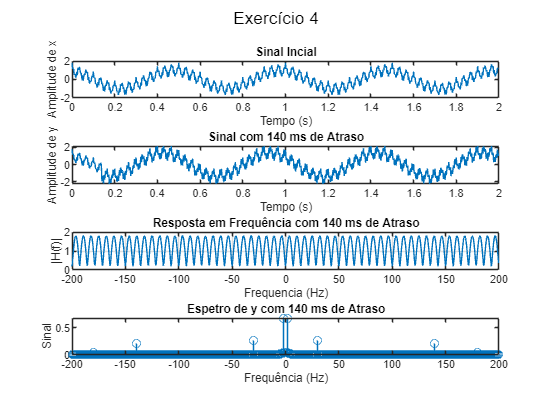


den = 1;
num = [1 zeros(1, D-1), -0.8];

figure;

y = filter(num,den,x);

subplot(4,1,1)
plot(t,x);
title('Sinal Incial');
xlabel('Tempo (s)');
ylabel('Amplitude de x');

subplot(4,1,2)
plot(t,y);
title('Sinal com 140 ms de Atraso');
xlabel('Tempo (s)');
ylabel('Amplitude de y');

subplot(4,1,3);
[H,f]=respfreq(num,den,fa);
title('Resposta em Frequência com 140 ms de Atraso')

subplot(4,1,4);
[Y, f1] = espetro(y,1/fa);
title('Espetro de y com 140 ms de Atraso')

sgtitle('Exercício 4');